data1 = readtable("data/Vibration dataset vs. wind speed/H-for Vw=1.3.csv")

data1 = 501×2 table
    Time_Sec    Amplitude_G
    ________    ___________

         0        0.006094 
     0.001        0.012603 
     0.002        0.006143 
     0.003        0.002501 
     0.004       -0.007711 
     0.005        -0.00054 
     0.006        0.003951 
     0.007        0.001744 
     0.008       -0.000882 
     0.009        0.000391 
      0.01        0.003549 
     0.011        0.004258 
     0.012       -0.007009 
     0.013        0.005691 
     0.014        0.005095 
     0.015        0.000858 


data2 = readtable("data/Vibration dataset vs. wind speed/UnbalanceState-Vw=1.3.csv")

data2 = 500×2 table
    Time_Voltage_1    Amplitude_Voltage_1
    ______________    ___________________

            0               0.003907     
        0.001               0.003311     
        0.002              -0.001187     
        0.003               0.005147     
        0.004               0.000701     
        0.005                0.00199     
        0.006               0.001764     
        0.007               0.001104     
        0.008               0.001088     
        0.009              -0.002912     
         0.01               0.000996     
        0.011              -0.005921     
        0.012              -0.002521     
        0.013              -0.004256     
        0.014               0.008386     
        0.015              -0.004216     


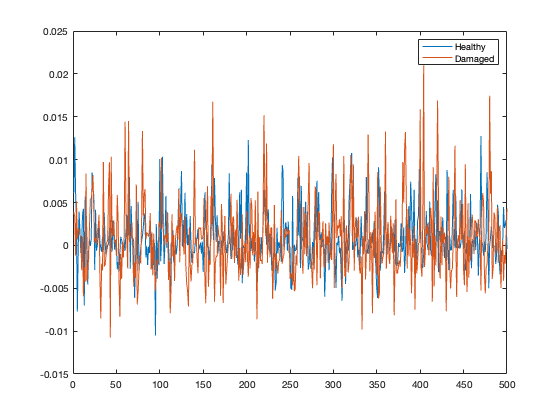

fs_healthy = data1.Amplitude_G(1:500);
fs_damaged = data2.Amplitude_Voltage_1;

figure;
plot(fs_healthy,"DisplayName","Healthy"); hold on; plot(fs_damaged,"DisplayName","Damaged")
legend();

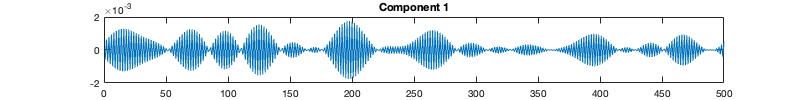

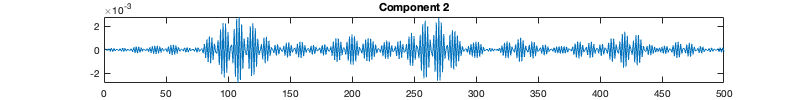

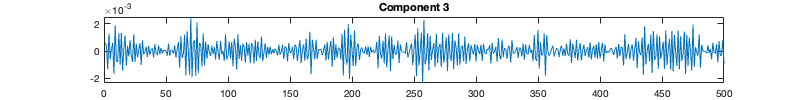

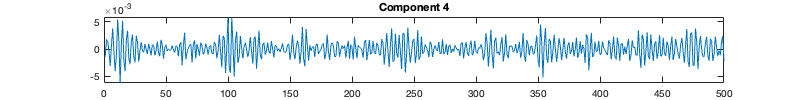

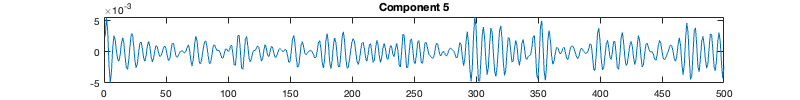

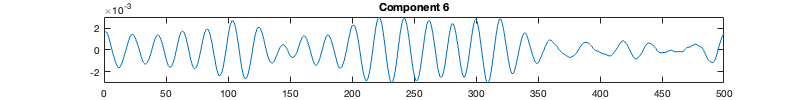

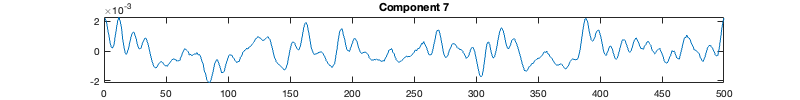

addpath ./SSD/
components_healthy=SSD(fs_healthy,1000);
components_damaged=SSD(fs_damaged,1000);

plot_SSD_components(1:500, components_healthy)

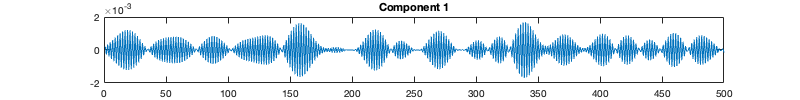

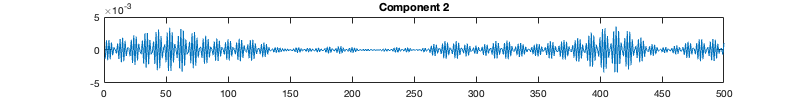

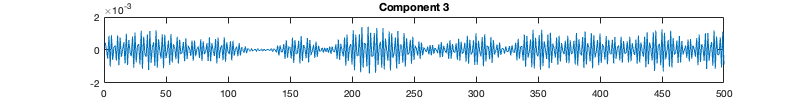

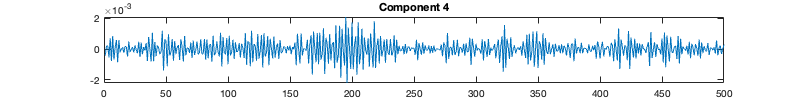

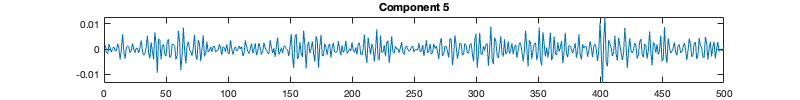

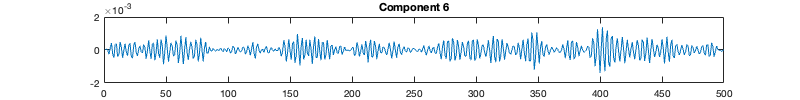

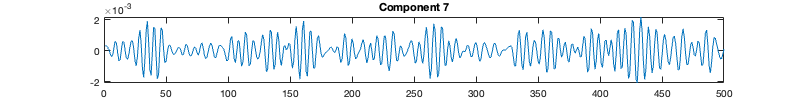

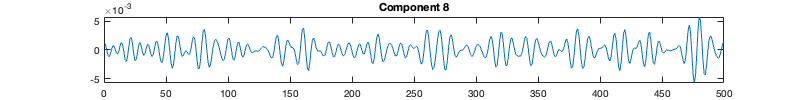

plot_SSD_components(1:500, components_damaged)